3.

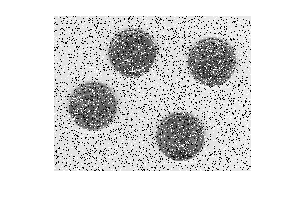

kuva1 = imread("suodatettava1.png");
kuva2 = imread("suodatettava2.png");
imshow(kuva1)

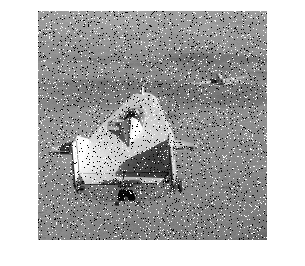

imshow(kuva2)

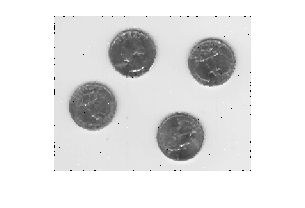

F1 = uint8(mediaani2(kuva1, 3, 3));
imshow(medfilt2(kuva1))

imshow(F1)

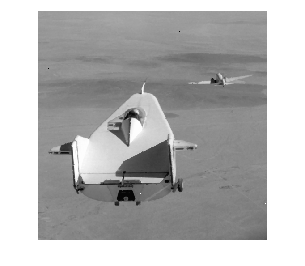

F2 = uint8(mediaani2(kuva2, 3, 3));
imshow(medfilt2(kuva2))

imshow(F2)

4.

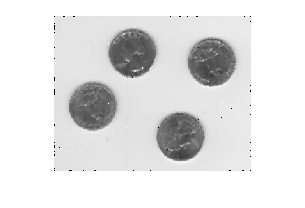

Fad1 = uint8(mediaani2ad(kuva1, 5));
imshow(Fad1)

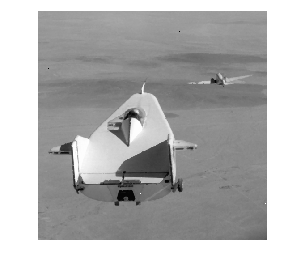

Fad2 = uint8(mediaani2ad(kuva2, 5));
imshow(Fad2)

tehtävän 4 filtterit toivat paremmat tulokset kuin tehtävän 3 filtterin, niihin jäi vähemmän kohinaa.

5.

i = imread("viitat.tiff");
filter = fspecial("gaussian",[11 11],sqrt(3));
image = psf2otf(filter, [256 256]);
fourier = fft2(image);


6.

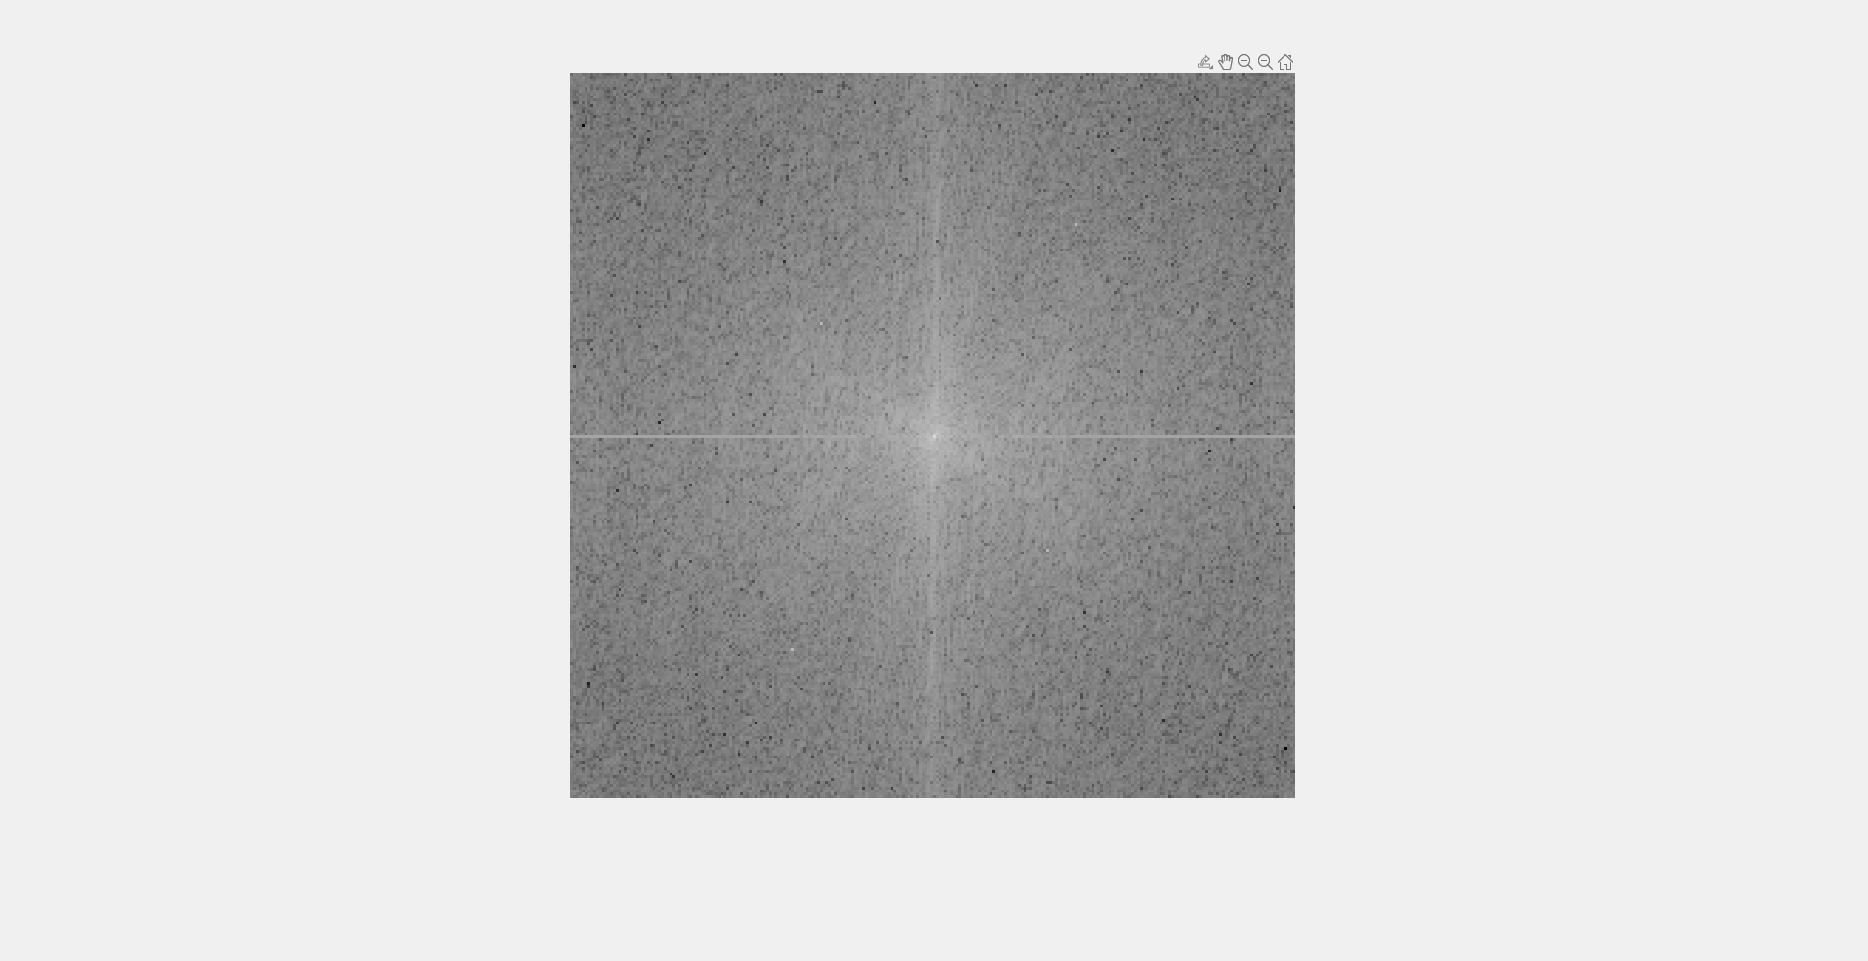

img = imread("noisyplane.tiff");
fourier = fft2(img);
centered = fftshift(fourier);
map = log10(abs(centered));
map = log10(map);
imshow(map)
[col, row] = ginput(4);

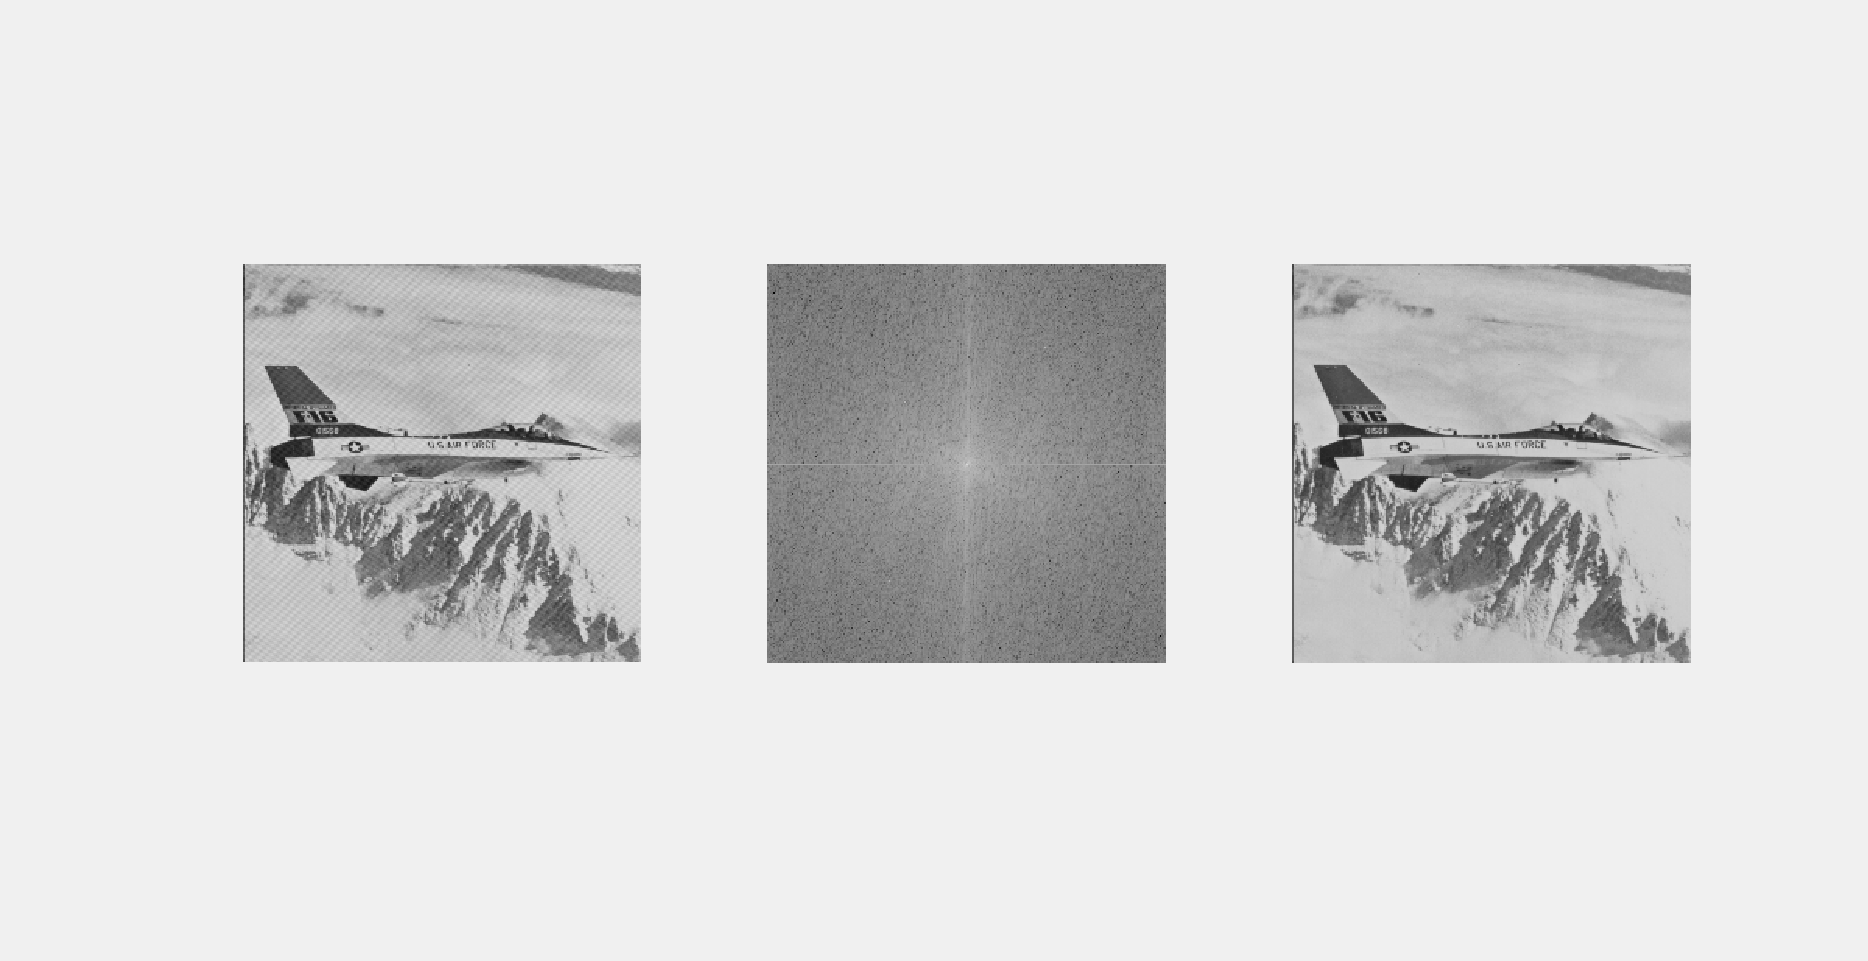

col = uint8(col);
row = uint8(row);
for i = 1 : 4
    alue = map((row(i)-5):(row(i)+5), (col(i)-5):(col(i)+5));
    [max_row,max_col]=find(alue==max(alue(:)));
    centered(row(i)-6+max_row, col(i)-6+max_col) = 0;
end
centered = ifftshift(centered);
centered = ifft2(centered);
centered = real(centered);
centered = uint8(centered);
subplot(1,3,1)
imshow(img)
subplot(1,3,2)
imshow(map)
subplot(1,3,3)
imshow(centered)